%AI-Based Diabetes Prediction Using Machine Learning, MATLAB and Simulink
%Project_card 
%% =========================================================
% ORIGINAL DIABETES CODE
% ==========================================================
diabetes = readtable('diabetes.csv')

diabetes = 768×9 table
    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age    Outcome
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___    _______

         6           148           72               35              0      33.6             0.627              50        1   
         1            85           66               29              0      26.6             0.351              31        0   
         8           183           64                0              0      23.3             0.672              32        1   
         1            89           66   

whos diabetes

  Name            Size            Bytes  Class    Attributes

  diabetes      768x9             58183  table              



X = diabetes(:,1:8)

X = 768×8 table
    Pregnancies    Glucose    BloodPressure    SkinThickness    Insulin    BMI     DiabetesPedigreeFunction    Age
    ___________    _______    _____________    _____________    _______    ____    ________________________    ___

         6           148           72               35              0      33.6             0.627              50 
         1            85           66               29              0      26.6             0.351              31 
         8           183           64                0              0      23.3             0.672              32 
         1            89           66               23             94      28.1             0.167              21 
         0           

X = table2array(X)

X =     6.0000  148.0000   72.0000   35.0000         0   33.6000    0.6270   50.0000
    1.0000   85.0000   66.0000   29.0000         0   26.6000    0.3510   31.0000
    8.0000  183.0000   64.0000         0         0   23.3000    0.6720   32.0000
    1.0000   89.0000   66.0000   23.0000   94.0000   28.1000    0.1670   21.0000
         0  137.0000   40.0000   35.0000  168.0000   43.1000    2.2880   33.0000
    5.0000  116.0000   74.0000         0         0   25.6000    0.2010   30.0000
    3.0000   78.0000   50.0000   32.0000   88.0000   31.0000    0.2480   26.0000
   10.0000  115.0000         0         0         0   35.3000    0.1340   29.0000
    2.0000  197.0000   70.0000   45.0000  543.0000   30.5000    0.1580   53.0000
    8.0000  125.0000   96.0000         0         0         0    0.2320   54.0000
    4.0000  110.0000   92.0000         0         0   37.6000    0.1910   30.0000
   10.0000  168.0000   74.0000         0         0   38.0000    0.5370   34.0000
   10.0000  139.0000   8

y = diabetes(:,9)

y = 768×1 table
    Outcome
    _______

       1   
       0   
       1   
       0   
       1   
       0   
       1   
       0   
       1   
       1   
       0   
       1   
       0   
       1   
       1   
       1   


y = table2array(y)

y =      1
     0
     1
     0
     1
     0
     1
     0
     1
     1
     0
     1
     0
     1
     1


% Specify the number of neurons in the hidden layer (default value is 10)
% Link to Patternnet documentation:
% https://www.mathworks.com/help/deeplearning/ref/patternnet.html
net = patternnet(20);
view(net)
[net, tr] = train(net, X', y');
%% =========================================================
% ADDITIONAL DIABETES FEATURES
% MODERN NETWORK FOR SIMULINK
% ==========================================================
% Convert target values 0 and 1 to categorical classes
Y = categorical(y,[0 1],["No Diabetes" "Diabetes"]);
% Number of observations
numSamples = size(X,1);
% Randomly divide data into training, validation and testing
rng(42);
idx = randperm(numSamples);
numTrain = round(0.70*numSamples);
numValidation = round(0.15*numSamples);
trainInd = idx(1:numTrain);
valInd = idx(numTrain+1:numTrain+numValidation);
testInd = idx(numTrain+numValidation+1:end);
% Training data
XTrain = X(trainInd,:);
YTrain = Y(trainInd);
% Validation data
XValidation = X(valInd,:);
YValidation = Y(valInd);
% Testing data
XTest = X(testInd,:);
YTest = Y(testInd);
%% Create modern network for Simulink
layers = [
    featureInputLayer(8,Normalization="zscore")
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(2)
    softmaxLayer
];
%% Training options
options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    MiniBatchSize=32, ...
    InitialLearnRate=0.001, ...
    ValidationData={XValidation,YValidation}, ...
    Plots="training-progress", ...
    Verbose=false);
%% Train modern diabetes network
diabetesNet = trainnet( ...
    XTrain, ...
    YTrain, ...
    layers, ...
    "crossentropy", ...
    options);
%% Save network for Simulink
save('diabetes_network.mat','diabetesNet');
disp('Diabetes network saved successfully for Simulink.');

Diabetes network saved successfully for Simulink.


%% =========================================================
% ADDITIONAL DIABETES TESTING
% ==========================================================
% Get prediction scores
testScores = predict(diabetesNet,XTest);
% Get class names
classNames = categories(Y);
% Find predicted class
[~,classIndex] = max(testScores,[],2);
% Convert predictions to categorical labels
predictedLabels = categorical( ...
    classNames(classIndex), ...
    classNames);
%% Test Accuracy
accuracy = mean(predictedLabels == YTest);
fprintf('Diabetes Test Accuracy = %.2f%%\n', ...
    accuracy*100);

Diabetes Test Accuracy = 80.00%


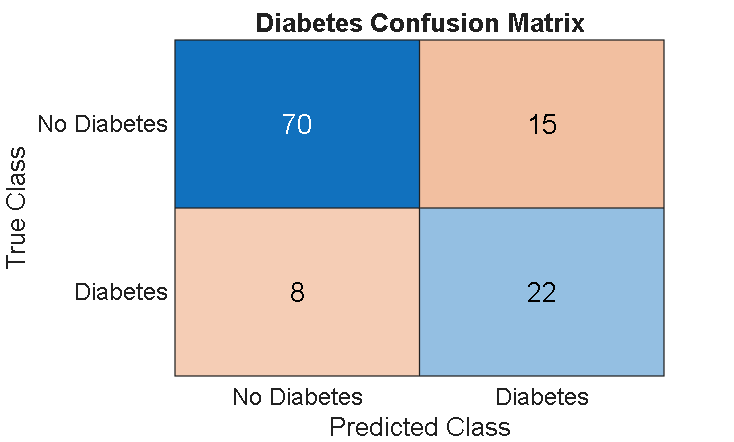

%% Confusion Matrix
figure
confusionchart(YTest,predictedLabels)
title('Diabetes Confusion Matrix');

%% =========================================================
% NEW PATIENT PREDICTION
% ==========================================================
newPatient = [2 120 70 25 80 28.5 0.5 35];
newPatientScores = predict( ...
    diabetesNet, ...
    newPatient);
disp('New Patient Prediction Scores:');

New Patient Prediction Scores:


disp(newPatientScores);

    0.7544    0.2456



[~,newClassIndex] = max(newPatientScores,[],2);
if newClassIndex == 2
    disp('Prediction: Diabetes')
else
    disp('Prediction: No Diabetes')
end

Prediction: No Diabetes


%% =========================================================
% ORIGINAL CANCER CODE
% ==========================================================
cancer = readtable('cancer.csv')

cancer = 569×31 table
    meanRadius    meanTexture    meanPerimeter    meanArea    meanSmoothness    meanCompactness    meanConcavity    meanConcavePoints    meanSymmetry    meanFractalDimension    radiusError    textureError    perimeterError    areaError    smoothnessError    compactnessError    concavityError    concavePointsError    symmetryError    fractalDimensionError    worstRadius    worstTexture    worstPerimeter    worstArea    worstSmoothness    worstCompactness    worstConcavity    worstConcavePoints    <

%plot(cancer(:,1), cancer(:,1))
whos cancer

  Name          Size             Bytes  Class    Attributes

  cancer      569x31            153995  table              



X = cancer(:,1:30)

X = 569×30 table
    meanRadius    meanTexture    meanPerimeter    meanArea    meanSmoothness    meanCompactness    meanConcavity    meanConcavePoints    meanSymmetry    meanFractalDimension    radiusError    textureError    perimeterError    areaError    smoothnessError    compactnessError    concavityError    concavePointsError    symmetryError    fractalDimensionError    worstRadius    worstTexture    worstPerimeter    worstArea    worstSmoothness    worstCompactness    worstConcavity    worstConcavePoints    

X = table2array(X)

X = 1.0e+03 *

    0.0180    0.0104    0.1228    1.0010    0.0001    0.0003    0.0003    0.0001    0.0002    0.0001    0.0011    0.0009    0.0086    0.1534    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0254    0.0173    0.1846    2.0190    0.0002    0.0007    0.0007    0.0003    0.0005    0.0001
    0.0206    0.0178    0.1329    1.3260    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0005    0.0007    0.0034    0.0741    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0250    0.0234    0.1588    1.9560    0.0001    0.0002    0.0002    0.0002    0.0003    0.0001
    0.0197    0.0213    0.1300    1.2030    0.0001    0.0002    0.0002    0.0001    0.0002    0.0001    0.0007    0.0008    0.0046    0.0940    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0236    0.0255    0.1525    1.7090    0.0001    0.0004    0.0005    0.0002    0.0004    0.0001
    0.0114    0.0204    0.0776    0.3861    0.0001    0.0003    0.0002    0.0001  

y = cancer(:,31)

y = 569×1 table
    target
    ______

      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   
      0   


y = table2array(y)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


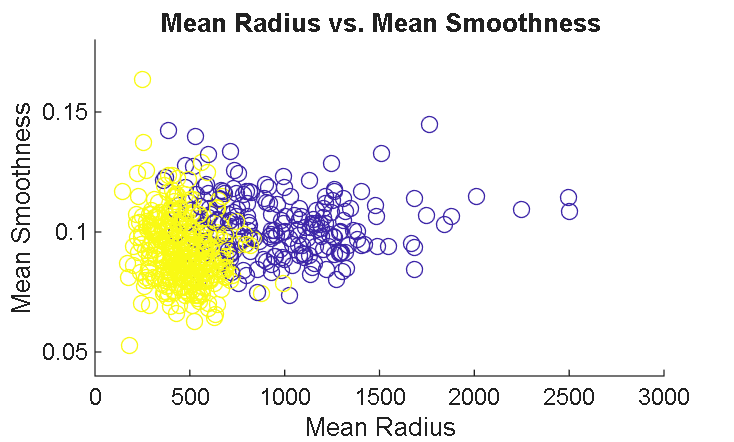

figure
scatter(X(:,4), X(:,5), [], y)
xlabel('Mean Radius')
ylabel('Mean Smoothness')
title('Mean Radius vs. Mean Smoothness')

%% Original cancer neural network
net = patternnet([10, 8, 5]);
view(net)
[net, tr] = train(net, X', y');
%% =========================================================
% ORIGINAL CANCER TESTING
% ==========================================================
testX = X(tr.testInd,:);
testY = y(tr.testInd);
prediction = net(testX');
prediction = round(prediction);
accuracy = sum(prediction == testY') / length(testY);
fprintf('Test Accuracy = %.2f%%\n', ...
    accuracy*100);

Test Accuracy = 98.82%


plotconfusion(testY',prediction);
%% =========================================================
% ORIGINAL NEW PATIENT SECTION
% ==========================================================
newPatient = [2 120 70 25 80 28.5 0.5 35];
prediction = net(newPatient');

Error using network/sim (line 270)
Input data sizes do not match net.inputs{1}.size.

Error in indexing (line 15)
        otherwise, v = sim(vin,subs{:});

if prediction >= 0.5
    disp('Prediction: Diabetes')
else
    disp('Prediction: No Diabetes')
end